# MATLAB Time Benchmark

This file compares time to access MATLAB matrices row and column wise.

% Preamble
close all
clear
clc

N = [2 5 10 100 500 1000 5000 10000 50000]; % 100,000 didn't fit in memory

## Row v Column Access

col_access = zeros(length(N), 2);
row_access = zeros(length(N), 2);
colT_access = zeros(length(N), 2);
rowT_access = zeros(length(N), 2);
transpose_op = zeros(length(N), 1);

for n_i=1:length(N)
    n = N(n_i);
    A = rand(n,n);          % Make matrix
    time = zeros(n,1);
    for i=1:n               % Access columns
        tic
        v1 = A(:,i);
        time(i) = toc;
        disp(mean(v1));
    end
    col_access(n_i, 1) = mean(time);
    col_access(n_i, 2) = std(time);
    for i=1:n               % Access rows
        tic
        v2 = A(i,:);
        time(i) = toc;
        disp(mean(v2));
    end
    row_access(n_i, 1) = mean(time);
    row_access(n_i, 2) = std(time);
    tic;
    A = A';
    transpose_op(n_i) = toc;
    for i=1:n               % Access columns
        tic
        v3 = A(:,i);
        time(i) = toc;
        disp(mean(v3));
    end
    colT_access(n_i, 1) = mean(time);
    colT_access(n_i, 2) = std(time);
    for i=1:n               % Access rows
        tic
        v4 = A(i,:);
        time(i) = toc;
        disp(mean(v4));
    end
    rowT_access(n_i, 1) = mean(time);
    rowT_access(n_i, 2) = std(time);
end

    0.3864

    0.7812



    0.6147

    0.5529



    0.6147

    0.5529



    0.3864

    0.7812



    0.5126

    0.4714

    0.4675

    0.4073

    0.6024



    0.4266

    0.5970

    0.3683

    0.6388

    0.4304



    0.4266

    0.5970

    0.3683

    0.6388

    0.4304



    0.5126

    0.4714

    0.4675

    0.4073

    0.6024



    0.5336

    0.6065

    0.5879

    0.5089

    0.3655

    0.3931

    0.5640

    0.4902

    0.4465

    0.3931



    0.4001

    0.4826

    0.3568

    0.5034

    0.6713

    0.4382

    0.4184

    0.5899

    0.5884

    0.4403



    0.4001

    0.4826

    0.3568

    0.5034

    0.6713

    0.4382

    0.4184

    0.5899

    0.5884

    0.4403



    0.5336

    0.6065

    0.5879

    0.5089

    0.3655

    0.3931

    0.5640

    0.4902

    0.4465

    0.3931



    0.4943

    0.4702

    0.4925

    0.4915

    0.4796

    0.4686

    0.5351

    0.4713

    0.4843

    0.4740

    0.5279

    0.4817

    0.4730

    0.4967

    0.5129

    0.5198

    0.4922

    0.5314

    0.5081

    0.4688

    0.4639

    0.4624

    0.4362

    0.5334

    0.5172

    0.5144

    0.5624

    0.4651

    0.5190

    0.5828

    0.5192

    0.5219

    0.4929

    0.5180

    0.4956

    0.4590

    0.5002

    0.5000

    0.4958

    0.5104

    0.4716

    0.5536

    0.5111

    0.4458

    0.5308

    0.4963

    0.5436

    0.4204

    0.5061

    0.5325

    0.5065

    0.5375

    0.5277

    0.4922

    0.4866

    0.5140

    0.4804

    0.5313

    0.5212

    0.4665

    0.5174

    0.4735

    0.4907

    0.4982

    0.5042

    0.4278

    0.4830

    0.4963

    0.5042

    0.5354

    0.4767

    0.4694

    0.4672

    0.5110

    0.4949

    0.4913

    0.5071

    0.5031

    0.4858

    0.5219

    0.4973

    0.4716

    0.4838

    

    0.5395

    0.4716

    0.5210

    0.4819

    0.4913

    0.5216

    0.5327

    0.5354

    0.5209

    0.4358

    0.4533

    0.4828

    0.5386

    0.5560

    0.4703

    0.4879

    0.4966

    0.5075

    0.4785

    0.4137

    0.5025

    0.4976

    0.5029

    0.4908

    0.5041

    0.5003

    0.4990

    0.4827

    0.4884

    0.5036

    0.4605

    0.5265

    0.4988

    0.4407

    0.5068

    0.4742

    0.5073

    0.4618

    0.5106

    0.5240

    0.5466

    0.4767

    0.5126

    0.4988

    0.5200

    0.5307

    0.4978

    0.4919

    0.5196

    0.4099

    0.4973

    0.5112

    0.5236

    0.4277

    0.4907

    0.5223

    0.5087

    0.4545

    0.5397

    0.4723

    0.5239

    0.4824

    0.5699

    0.5579

    0.4832

    0.5023

    0.4847

    0.4940

    0.5198

    0.5003

    0.4981

    0.5335

    0.4719

    0.4975

    0.5283

    0.5159

    0.4748

    0.4960

    0.5133

    0.4908

    0.5085

    0.4927

    0.4755

    

    0.5395

    0.4716

    0.5210

    0.4819

    0.4913

    0.5216

    0.5327

    0.5354

    0.5209

    0.4358

    0.4533

    0.4828

    0.5386

    0.5560

    0.4703

    0.4879

    0.4966

    0.5075

    0.4785

    0.4137

    0.5025

    0.4976

    0.5029

    0.4908

    0.5041

    0.5003

    0.4990

    0.4827

    0.4884

    0.5036

    0.4605

    0.5265

    0.4988

    0.4407

    0.5068

    0.4742

    0.5073

    0.4618

    0.5106

    0.5240

    0.5466

    0.4767

    0.5126

    0.4988

    0.5200

    0.5307

    0.4978

    0.4919

    0.5196

    0.4099

    0.4973

    0.5112

    0.5236

    0.4277

    0.4907

    0.5223

    0.5087

    0.4545

    0.5397

    0.4723

    0.5239

    0.4824

    0.5699

    0.5579

    0.4832

    0.5023

    0.4847

    0.4940

    0.5198

    0.5003

    0.4981

    0.5335

    0.4719

    0.4975

    0.5283

    0.5159

    0.4748

    0.4960

    0.5133

    0.4908

    0.5085

    0.4927

    0.4755

    

    0.4943

    0.4702

    0.4925

    0.4915

    0.4796

    0.4686

    0.5351

    0.4713

    0.4843

    0.4740

    0.5279

    0.4817

    0.4730

    0.4967

    0.5129

    0.5198

    0.4922

    0.5314

    0.5081

    0.4688

    0.4639

    0.4624

    0.4362

    0.5334

    0.5172

    0.5144

    0.5624

    0.4651

    0.5190

    0.5828

    0.5192

    0.5219

    0.4929

    0.5180

    0.4956

    0.4590

    0.5002

    0.5000

    0.4958

    0.5104

    0.4716

    0.5536

    0.5111

    0.4458

    0.5308

    0.4963

    0.5436

    0.4204

    0.5061

    0.5325

    0.5065

    0.5375

    0.5277

    0.4922

    0.4866

    0.5140

    0.4804

    0.5313

    0.5212

    0.4665

    0.5174

    0.4735

    0.4907

    0.4982

    0.5042

    0.4278

    0.4830

    0.4963

    0.5042

    0.5354

    0.4767

    0.4694

    0.4672

    0.5110

    0.4949

    0.4913

    0.5071

    0.5031

    0.4858

    0.5219

    0.4973

    0.4716

    0.4838

    

    0.5126

    0.4961

    0.5216

    0.5008

    0.4981

    0.5068

    0.4892

    0.4982

    0.4854

    0.5083

    0.4677

    0.4920

    0.4986

    0.5241

    0.4988

    0.5149

    0.4870

    0.5124

    0.5026

    0.4982

    0.4965

    0.4743

    0.5005

    0.4851

    0.4920

    0.4856

    0.4993

    0.4970

    0.5155

    0.5114

    0.4906

    0.4831

    0.4745

    0.4879

    0.4973

    0.5122

    0.5003

    0.5001

    0.4933

    0.4999

    0.4862

    0.5022

    0.4930

    0.4988

    0.5034

    0.5244

    0.4884

    0.4928

    0.4977

    0.4836

    0.4898

    0.4919

    0.4995

    0.4835

    0.4765

    0.5073

    0.5012

    0.5057

    0.5215

    0.5180

    0.4799

    0.5243

    0.4956

    0.5002

    0.5015

    0.5010

    0.5233

    0.4803

    0.4868

    0.4887

    0.5108

    0.4744

    0.4999

    0.5046

    0.4959

    0.5002

    0.5051

    0.4940

    0.5248

    0.4757

    0.5039

    0.5041

    0.4958

    

    0.4840

    0.5065

    0.4808

    0.4855

    0.4830

    0.4835

    0.4785

    0.4918

    0.4827

    0.5198

    0.5055

    0.5209

    0.5120

    0.5026

    0.5249

    0.4827

    0.4842

    0.4900

    0.4924

    0.4944

    0.5185

    0.4925

    0.4878

    0.5085

    0.5016

    0.5314

    0.5370

    0.4635

    0.4975

    0.5166

    0.5065

    0.5098

    0.4764

    0.4891

    0.5232

    0.4890

    0.4897

    0.5113

    0.4818

    0.4959

    0.5154

    0.5265

    0.5120

    0.4646

    0.4994

    0.5097

    0.5008

    0.5059

    0.5047

    0.4998

    0.5093

    0.4967

    0.5218

    0.4840

    0.4997

    0.4966

    0.4911

    0.5023

    0.5284

    0.4895

    0.5007

    0.5165

    0.5143

    0.4886

    0.5074

    0.4996

    0.4925

    0.4819

    0.5063

    0.5001

    0.4994

    0.4908

    0.5112

    0.4910

    0.4981

    0.4957

    0.5175

    0.5018

    0.5220

    0.5012

    0.5130

    0.5075

    0.5025

    

    0.4840

    0.5065

    0.4808

    0.4855

    0.4830

    0.4835

    0.4785

    0.4918

    0.4827

    0.5198

    0.5055

    0.5209

    0.5120

    0.5026

    0.5249

    0.4827

    0.4842

    0.4900

    0.4924

    0.4944

    0.5185

    0.4925

    0.4878

    0.5085

    0.5016

    0.5314

    0.5370

    0.4635

    0.4975

    0.5166

    0.5065

    0.5098

    0.4764

    0.4891

    0.5232

    0.4890

    0.4897

    0.5113

    0.4818

    0.4959

    0.5154

    0.5265

    0.5120

    0.4646

    0.4994

    0.5097

    0.5008

    0.5059

    0.5047

    0.4998

    0.5093

    0.4967

    0.5218

    0.4840

    0.4997

    0.4966

    0.4911

    0.5023

    0.5284

    0.4895

    0.5007

    0.5165

    0.5143

    0.4886

    0.5074

    0.4996

    0.4925

    0.4819

    0.5063

    0.5001

    0.4994

    0.4908

    0.5112

    0.4910

    0.4981

    0.4957

    0.5175

    0.5018

    0.5220

    0.5012

    0.5130

    0.5075

    0.5025

    

    0.5126

    0.4961

    0.5216

    0.5008

    0.4981

    0.5068

    0.4892

    0.4982

    0.4854

    0.5083

    0.4677

    0.4920

    0.4986

    0.5241

    0.4988

    0.5149

    0.4870

    0.5124

    0.5026

    0.4982

    0.4965

    0.4743

    0.5005

    0.4851

    0.4920

    0.4856

    0.4993

    0.4970

    0.5155

    0.5114

    0.4906

    0.4831

    0.4745

    0.4879

    0.4973

    0.5122

    0.5003

    0.5001

    0.4933

    0.4999

    0.4862

    0.5022

    0.4930

    0.4988

    0.5034

    0.5244

    0.4884

    0.4928

    0.4977

    0.4836

    0.4898

    0.4919

    0.4995

    0.4835

    0.4765

    0.5073

    0.5012

    0.5057

    0.5215

    0.5180

    0.4799

    0.5243

    0.4956

    0.5002

    0.5015

    0.5010

    0.5233

    0.4803

    0.4868

    0.4887

    0.5108

    0.4744

    0.4999

    0.5046

    0.4959

    0.5002

    0.5051

    0.4940

    0.5248

    0.4757

    0.5039

    0.5041

    0.4958

    

    0.5013

    0.4952

    0.4933

    0.5007

    0.5021

    0.4953

    0.5060

    0.4916

    0.4975

    0.5176

    0.4928

    0.5037

    0.5154

    0.5107

    0.4924

    0.5080

    0.5027

    0.4869

    0.4958

    0.4910

    0.5009

    0.4850

    0.5078

    0.4980

    0.5055

    0.5033

    0.4972

    0.4860

    0.5018

    0.4881

    0.4942

    0.4916

    0.4962

    0.4849

    0.4980

    0.4961

    0.4878

    0.5024

    0.5030

    0.4888

    0.5134

    0.4917

    0.5009

    0.5021

    0.5085

    0.5013

    0.5071

    0.4917

    0.4926

    0.4976

    0.5034

    0.4818

    0.4952

    0.5137

    0.5000

    0.5101

    0.4914

    0.5006

    0.5030

    0.5000

    0.5115

    0.4976

    0.4901

    0.5114

    0.4928

    0.5046

    0.4980

    0.5089

    0.5119

    0.4984

    0.5143

    0.5128

    0.5124

    0.5087

    0.4888

    0.5024

    0.5061

    0.4913

    0.5000

    0.5026

    0.5074

    0.5058

    0.5006

    

    0.5074

    0.5037

    0.4980

    0.4978

    0.5007

    0.5027

    0.4863

    0.5050

    0.4903

    0.5094

    0.4840

    0.4998

    0.5010

    0.5087

    0.4913

    0.4974

    0.4843

    0.4948

    0.4982

    0.5089

    0.4849

    0.5075

    0.4987

    0.5055

    0.5027

    0.4975

    0.5036

    0.5034

    0.4916

    0.4902

    0.4932

    0.4905

    0.5249

    0.4967

    0.4862

    0.4878

    0.4832

    0.4956

    0.5020

    0.4906

    0.4954

    0.4959

    0.5045

    0.5060

    0.4891

    0.5125

    0.4949

    0.4991

    0.4959

    0.5118

    0.5057

    0.5015

    0.4999

    0.4866

    0.4978

    0.4844

    0.4830

    0.4976

    0.5109

    0.4823

    0.5057

    0.5051

    0.5032

    0.4918

    0.5011

    0.5034

    0.4976

    0.4851

    0.4975

    0.4966

    0.4991

    0.5043

    0.5037

    0.4860

    0.5017

    0.5043

    0.5039

    0.5015

    0.5101

    0.4996

    0.4878

    0.5113

    0.5065

    

    0.5074

    0.5037

    0.4980

    0.4978

    0.5007

    0.5027

    0.4863

    0.5050

    0.4903

    0.5094

    0.4840

    0.4998

    0.5010

    0.5087

    0.4913

    0.4974

    0.4843

    0.4948

    0.4982

    0.5089

    0.4849

    0.5075

    0.4987

    0.5055

    0.5027

    0.4975

    0.5036

    0.5034

    0.4916

    0.4902

    0.4932

    0.4905

    0.5249

    0.4967

    0.4862

    0.4878

    0.4832

    0.4956

    0.5020

    0.4906

    0.4954

    0.4959

    0.5045

    0.5060

    0.4891

    0.5125

    0.4949

    0.4991

    0.4959

    0.5118

    0.5057

    0.5015

    0.4999

    0.4866

    0.4978

    0.4844

    0.4830

    0.4976

    0.5109

    0.4823

    0.5057

    0.5051

    0.5032

    0.4918

    0.5011

    0.5034

    0.4976

    0.4851

    0.4975

    0.4966

    0.4991

    0.5043

    0.5037

    0.4860

    0.5017

    0.5043

    0.5039

    0.5015

    0.5101

    0.4996

    0.4878

    0.5113

    0.5065

    

    0.5013

    0.4952

    0.4933

    0.5007

    0.5021

    0.4953

    0.5060

    0.4916

    0.4975

    0.5176

    0.4928

    0.5037

    0.5154

    0.5107

    0.4924

    0.5080

    0.5027

    0.4869

    0.4958

    0.4910

    0.5009

    0.4850

    0.5078

    0.4980

    0.5055

    0.5033

    0.4972

    0.4860

    0.5018

    0.4881

    0.4942

    0.4916

    0.4962

    0.4849

    0.4980

    0.4961

    0.4878

    0.5024

    0.5030

    0.4888

    0.5134

    0.4917

    0.5009

    0.5021

    0.5085

    0.5013

    0.5071

    0.4917

    0.4926

    0.4976

    0.5034

    0.4818

    0.4952

    0.5137

    0.5000

    0.5101

    0.4914

    0.5006

    0.5030

    0.5000

    0.5115

    0.4976

    0.4901

    0.5114

    0.4928

    0.5046

    0.4980

    0.5089

    0.5119

    0.4984

    0.5143

    0.5128

    0.5124

    0.5087

    0.4888

    0.5024

    0.5061

    0.4913

    0.5000

    0.5026

    0.5074

    0.5058

    0.5006

    

    0.4987

    0.4942

    0.5013

    0.5028

    0.4966

    0.5002

    0.5032

    0.4988

    0.4948

    0.5041

    0.5000

    0.5034

    0.5065

    0.5045

    0.5015

    0.4976

    0.4961

    0.5008

    0.4985

    0.4990

    0.5046

    0.4979

    0.4972

    0.4975

    0.4997

    0.4975

    0.5014

    0.4911

    0.4962

    0.5072

    0.5045

    0.4968

    0.5016

    0.4965

    0.4966

    0.4950

    0.4956

    0.5075

    0.5002

    0.4980

    0.5019

    0.5031

    0.5013

    0.4988

    0.5022

    0.4985

    0.5001

    0.4994

    0.4991

    0.5032

    0.5006

    0.5004

    0.5052

    0.4995

    0.4981

    0.4989

    0.4958

    0.4946

    0.5096

    0.4981

    0.4957

    0.5003

    0.4994

    0.5075

    0.5012

    0.5018

    0.5041

    0.4995

    0.5140

    0.4986

    0.5018

    0.5020

    0.4998

    0.5079

    0.5007

    0.4977

    0.4966

    0.5018

    0.5028

    0.4926

    0.4959

    0.5005

    0.4999

    

    0.4997

    0.4980

    0.4859

    0.4917

    0.5023

    0.4994

    0.4989

    0.4967

    0.4978

    0.4979

    0.4971

    0.4912

    0.5020

    0.4930

    0.4962

    0.5037

    0.5025

    0.4927

    0.5000

    0.4948

    0.4996

    0.4999

    0.4978

    0.4958

    0.5040

    0.5004

    0.5001

    0.5003

    0.5069

    0.5065

    0.5000

    0.5016

    0.5048

    0.4986

    0.4950

    0.4994

    0.5045

    0.4992

    0.5070

    0.4920

    0.5015

    0.5031

    0.4920

    0.5048

    0.5004

    0.5041

    0.5045

    0.4979

    0.4965

    0.5015

    0.4954

    0.5023

    0.4974

    0.5008

    0.4960

    0.4907

    0.5000

    0.4957

    0.5005

    0.4991

    0.4985

    0.5007

    0.5038

    0.5007

    0.5098

    0.4980

    0.5053

    0.5014

    0.4982

    0.5004

    0.4955

    0.5048

    0.4996

    0.4973

    0.5012

    0.5006

    0.5017

    0.5024

    0.5022

    0.4990

    0.4982

    0.4992

    0.5024

    

    0.4997

    0.4980

    0.4859

    0.4917

    0.5023

    0.4994

    0.4989

    0.4967

    0.4978

    0.4979

    0.4971

    0.4912

    0.5020

    0.4930

    0.4962

    0.5037

    0.5025

    0.4927

    0.5000

    0.4948

    0.4996

    0.4999

    0.4978

    0.4958

    0.5040

    0.5004

    0.5001

    0.5003

    0.5069

    0.5065

    0.5000

    0.5016

    0.5048

    0.4986

    0.4950

    0.4994

    0.5045

    0.4992

    0.5070

    0.4920

    0.5015

    0.5031

    0.4920

    0.5048

    0.5004

    0.5041

    0.5045

    0.4979

    0.4965

    0.5015

    0.4954

    0.5023

    0.4974

    0.5008

    0.4960

    0.4907

    0.5000

    0.4957

    0.5005

    0.4991

    0.4985

    0.5007

    0.5038

    0.5007

    0.5098

    0.4980

    0.5053

    0.5014

    0.4982

    0.5004

    0.4955

    0.5048

    0.4996

    0.4973

    0.5012

    0.5006

    0.5017

    0.5024

    0.5022

    0.4990

    0.4982

    0.4992

    0.5024

    

    0.4987

    0.4942

    0.5013

    0.5028

    0.4966

    0.5002

    0.5032

    0.4988

    0.4948

    0.5041

    0.5000

    0.5034

    0.5065

    0.5045

    0.5015

    0.4976

    0.4961

    0.5008

    0.4985

    0.4990

    0.5046

    0.4979

    0.4972

    0.4975

    0.4997

    0.4975

    0.5014

    0.4911

    0.4962

    0.5072

    0.5045

    0.4968

    0.5016

    0.4965

    0.4966

    0.4950

    0.4956

    0.5075

    0.5002

    0.4980

    0.5019

    0.5031

    0.5013

    0.4988

    0.5022

    0.4985

    0.5001

    0.4994

    0.4991

    0.5032

    0.5006

    0.5004

    0.5052

    0.4995

    0.4981

    0.4989

    0.4958

    0.4946

    0.5096

    0.4981

    0.4957

    0.5003

    0.4994

    0.5075

    0.5012

    0.5018

    0.5041

    0.4995

    0.5140

    0.4986

    0.5018

    0.5020

    0.4998

    0.5079

    0.5007

    0.4977

    0.4966

    0.5018

    0.5028

    0.4926

    0.4959

    0.5005

    0.4999

    

    0.4986

    0.5044

    0.5003

    0.4949

    0.5012

    0.4993

    0.4967

    0.5002

    0.4986

    0.4983

    0.4997

    0.5012

    0.4986

    0.5036

    0.5018

    0.5044

    0.5023

    0.4955

    0.4966

    0.5001

    0.5019

    0.4956

    0.5006

    0.4994

    0.5024

    0.4988

    0.5007

    0.5070

    0.4948

    0.5021

    0.5030

    0.4955

    0.5039

    0.4960

    0.5018

    0.5056

    0.4992

    0.5013

    0.5005

    0.4987

    0.5006

    0.5061

    0.4997

    0.5003

    0.5033

    0.4969

    0.5011

    0.4991

    0.5028

    0.5016

    0.5026

    0.5010

    0.5010

    0.4990

    0.5019

    0.5080

    0.5024

    0.5009

    0.4981

    0.4992

    0.5008

    0.5033

    0.5029

    0.5021

    0.5000

    0.5021

    0.5030

    0.4988

    0.4995

    0.5001

    0.4993

    0.4984

    0.5017

    0.5022

    0.4995

    0.5037

    0.5036

    0.4953

    0.4981

    0.4930

    0.5040

    0.5008

    0.4980

    

    0.4984

    0.5048

    0.5077

    0.4984

    0.5027

    0.5006

    0.4964

    0.4993

    0.4968

    0.4989

    0.5036

    0.5002

    0.4983

    0.4998

    0.4949

    0.4987

    0.5019

    0.5023

    0.4979

    0.5006

    0.5033

    0.5016

    0.5012

    0.4990

    0.5007

    0.5032

    0.5038

    0.4988

    0.4992

    0.5073

    0.4949

    0.4985

    0.4997

    0.4957

    0.4997

    0.5041

    0.5042

    0.5029

    0.5005

    0.4978

    0.4991

    0.5020

    0.5023

    0.5009

    0.4976

    0.5000

    0.4965

    0.5033

    0.5038

    0.5048

    0.4988

    0.5015

    0.5074

    0.5007

    0.5063

    0.4984

    0.5012

    0.4995

    0.5014

    0.5000

    0.5001

    0.4987

    0.4973

    0.5015

    0.4989

    0.5070

    0.5019

    0.4962

    0.5046

    0.4989

    0.5029

    0.4990

    0.4966

    0.4932

    0.4999

    0.4994

    0.4973

    0.5017

    0.4975

    0.4979

    0.5007

    0.5030

    0.5012

    

    0.4984

    0.5048

    0.5077

    0.4984

    0.5027

    0.5006

    0.4964

    0.4993

    0.4968

    0.4989

    0.5036

    0.5002

    0.4983

    0.4998

    0.4949

    0.4987

    0.5019

    0.5023

    0.4979

    0.5006

    0.5033

    0.5016

    0.5012

    0.4990

    0.5007

    0.5032

    0.5038

    0.4988

    0.4992

    0.5073

    0.4949

    0.4985

    0.4997

    0.4957

    0.4997

    0.5041

    0.5042

    0.5029

    0.5005

    0.4978

    0.4991

    0.5020

    0.5023

    0.5009

    0.4976

    0.5000

    0.4965

    0.5033

    0.5038

    0.5048

    0.4988

    0.5015

    0.5074

    0.5007

    0.5063

    0.4984

    0.5012

    0.4995

    0.5014

    0.5000

    0.5001

    0.4987

    0.4973

    0.5015

    0.4989

    0.5070

    0.5019

    0.4962

    0.5046

    0.4989

    0.5029

    0.4990

    0.4966

    0.4932

    0.4999

    0.4994

    0.4973

    0.5017

    0.4975

    0.4979

    0.5007

    0.5030

    0.5012

    

    0.4986

    0.5044

    0.5003

    0.4949

    0.5012

    0.4993

    0.4967

    0.5002

    0.4986

    0.4983

    0.4997

    0.5012

    0.4986

    0.5036

    0.5018

    0.5044

    0.5023

    0.4955

    0.4966

    0.5001

    0.5019

    0.4956

    0.5006

    0.4994

    0.5024

    0.4988

    0.5007

    0.5070

    0.4948

    0.5021

    0.5030

    0.4955

    0.5039

    0.4960

    0.5018

    0.5056

    0.4992

    0.5013

    0.5005

    0.4987

    0.5006

    0.5061

    0.4997

    0.5003

    0.5033

    0.4969

    0.5011

    0.4991

    0.5028

    0.5016

    0.5026

    0.5010

    0.5010

    0.4990

    0.5019

    0.5080

    0.5024

    0.5009

    0.4981

    0.4992

    0.5008

    0.5033

    0.5029

    0.5021

    0.5000

    0.5021

    0.5030

    0.4988

    0.4995

    0.5001

    0.4993

    0.4984

    0.5017

    0.5022

    0.4995

    0.5037

    0.5036

    0.4953

    0.4981

    0.4930

    0.5040

    0.5008

    0.4980

    

    0.5000

    0.5016

    0.4989

    0.5004

    0.5002

    0.4988

    0.5011

    0.5000

    0.4992

    0.4975

    0.5000

    0.5008

    0.5010

    0.4997

    0.4984

    0.4990

    0.5025

    0.4993

    0.5006

    0.5008

    0.4988

    0.5013

    0.5000

    0.5004

    0.5002

    0.5000

    0.5017

    0.4993

    0.4976

    0.5000

    0.5009

    0.5001

    0.4995

    0.4982

    0.5016

    0.4991

    0.4982

    0.5008

    0.4997

    0.5007

    0.5013

    0.5001

    0.4999

    0.5005

    0.4975

    0.5012

    0.5019

    0.4995

    0.5006

    0.5005

    0.4982

    0.4979

    0.5003

    0.5006

    0.4976

    0.4993

    0.5002

    0.5009

    0.5026

    0.5013

    0.4998

    0.5009

    0.4979

    0.5003

    0.4984

    0.4997

    0.5006

    0.5007

    0.4992

    0.5000

    0.5003

    0.4999

    0.4990

    0.4982

    0.5001

    0.4990

    0.4986

    0.5000

    0.4983

    0.5005

    0.5000

    0.5000

    0.5018

    

    0.4992

    0.4996

    0.5001

    0.4989

    0.4997

    0.4992

    0.4994

    0.4979

    0.5008

    0.5007

    0.4977

    0.4997

    0.4985

    0.5010

    0.5007

    0.5012

    0.5011

    0.5013

    0.5007

    0.5015

    0.4995

    0.5028

    0.4988

    0.5009

    0.4990

    0.4991

    0.5014

    0.5009

    0.5023

    0.4995

    0.5018

    0.5013

    0.5031

    0.5005

    0.4989

    0.4987

    0.4994

    0.5005

    0.4999

    0.4968

    0.5001

    0.5005

    0.4978

    0.4981

    0.4980

    0.5028

    0.5019

    0.5001

    0.5002

    0.5013

    0.5008

    0.5017

    0.4978

    0.4998

    0.5020

    0.4988

    0.4993

    0.4974

    0.5001

    0.4994

    0.5005

    0.5014

    0.5017

    0.5016

    0.4994

    0.4986

    0.5035

    0.5001

    0.4996

    0.4987

    0.5019

    0.4989

    0.4996

    0.4997

    0.4979

    0.5046

    0.5006

    0.4985

    0.5007

    0.4998

    0.5006

    0.4980

    0.5002

    

    0.4992

    0.4996

    0.5001

    0.4989

    0.4997

    0.4992

    0.4994

    0.4979

    0.5008

    0.5007

    0.4977

    0.4997

    0.4985

    0.5010

    0.5007

    0.5012

    0.5011

    0.5013

    0.5007

    0.5015

    0.4995

    0.5028

    0.4988

    0.5009

    0.4990

    0.4991

    0.5014

    0.5009

    0.5023

    0.4995

    0.5018

    0.5013

    0.5031

    0.5005

    0.4989

    0.4987

    0.4994

    0.5005

    0.4999

    0.4968

    0.5001

    0.5005

    0.4978

    0.4981

    0.4980

    0.5028

    0.5019

    0.5001

    0.5002

    0.5013

    0.5008

    0.5017

    0.4978

    0.4998

    0.5020

    0.4988

    0.4993

    0.4974

    0.5001

    0.4994

    0.5005

    0.5014

    0.5017

    0.5016

    0.4994

    0.4986

    0.5035

    0.5001

    0.4996

    0.4987

    0.5019

    0.4989

    0.4996

    0.4997

    0.4979

    0.5046

    0.5006

    0.4985

    0.5007

    0.4998

    0.5006

    0.4980

    0.5002

    

    0.5000

    0.5016

    0.4989

    0.5004

    0.5002

    0.4988

    0.5011

    0.5000

    0.4992

    0.4975

    0.5000

    0.5008

    0.5010

    0.4997

    0.4984

    0.4990

    0.5025

    0.4993

    0.5006

    0.5008

    0.4988

    0.5013

    0.5000

    0.5004

    0.5002

    0.5000

    0.5017

    0.4993

    0.4976

    0.5000

    0.5009

    0.5001

    0.4995

    0.4982

    0.5016

    0.4991

    0.4982

    0.5008

    0.4997

    0.5007

    0.5013

    0.5001

    0.4999

    0.5005

    0.4975

    0.5012

    0.5019

    0.4995

    0.5006

    0.5005

    0.4982

    0.4979

    0.5003

    0.5006

    0.4976

    0.4993

    0.5002

    0.5009

    0.5026

    0.5013

    0.4998

    0.5009

    0.4979

    0.5003

    0.4984

    0.4997

    0.5006

    0.5007

    0.4992

    0.5000

    0.5003

    0.4999

    0.4990

    0.4982

    0.5001

    0.4990

    0.4986

    0.5000

    0.4983

    0.5005

    0.5000

    0.5000

    0.5018

    

## Make plot

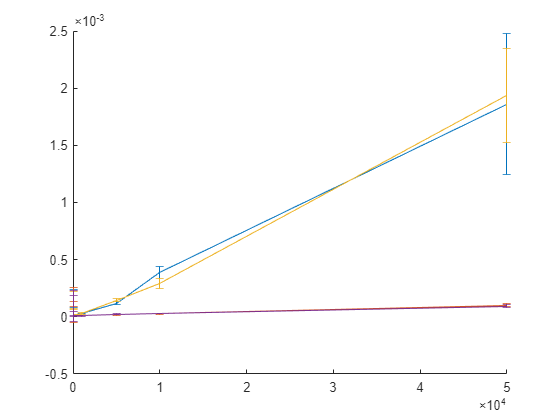

figure; hold on;
errorbar(N, row_access(:,1), row_access(:, 2))
errorbar(N, col_access(:,1), col_access(:, 2))
errorbar(N, rowT_access(:,1), rowT_access(:, 2))
errorbar(N, colT_access(:,1), colT_access(:, 2))